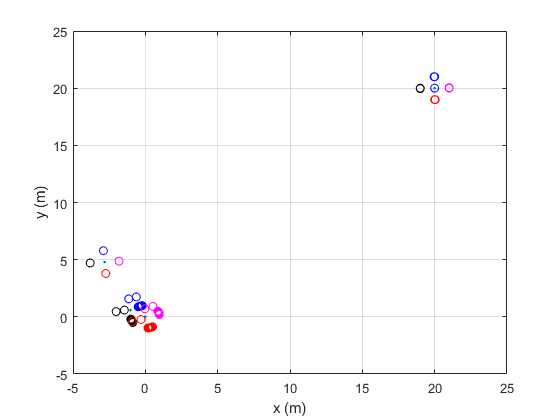

clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=4; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.5;
D=1; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
plot(c0(1,1),c0(2,1),'ob')
hold on
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo
k=1.1;
c1=10^-4;
c2=0.1; %Parámetros para el line search

colors=["ob","ok","or","om","og"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(2,N,iteration);
i=1;

while mod_rc>0.001
    grad_sum=0;
    if i==500
        break
    end
    
    %Aproximación del gradiente en el centro    
    grad_centr(:,i)=gradient_point2D(c(:,i),t(i),N,D,S,w0);
    %Posición de los robots
    pos_rob(:,1:N,i)=posicion_robots(c0,N,D,w0,i,t);
    %Dirección de descenso
    p(:,i)=-grad_centr(:,i);
        %Aplicación del método del gradiente ascendente
    alpha1=1;
    steplengthParam=[c1,c2,alpha1,k];
    alpha(i)=alpha_strongWolfe(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0);
    c(:,i+1)=c(:,i)+alpha(i)*p(:,i);
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
    i=i+1;
end
%Representación del centro
plot(c(1,:),c(2,:),'.')
grid on
hold on
%Representación de los robots
for g=1:N
    for z=1:length(mod_r_c)
        plot(pos_rob(1,g,z),pos_rob(2,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
hold off

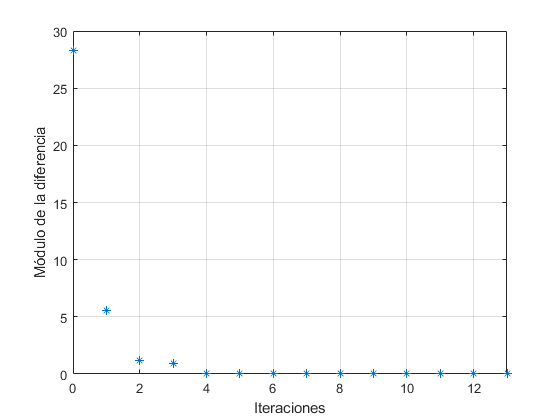

plot(0:length(mod_r_c)-1,mod_r_c,"*")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on
xlim([0 13])
hold off


%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 9.7645e-04

c0

c0 = 	1.0e+-3 *

   -0.6280
    0.7477
